Segmentation workflow with all parameters (teaching material, might be different from current code... )

path = '..\data\240828_AUZ0752_OD_HD_0';
PW_params = Parameters_json(path);

V = VideoReader([path,'\avi\240828_AUZ0752_OD_HD_0_M0.avi']);
video = zeros(V.Height, V.Width, V.NumFrames,'single');
[Ny,Nx,Nt] = size(video);
for n = 1:V.NumFrames
    video(:, :, n) = rgb2gray(read(V, n));
end


V = VideoReader([path,'\avi\240828_AUZ0752_OD_HD_0_moment1.avi']);
videoCRA = zeros(V.Height, V.Width, V.NumFrames,'single');
[Ny,Nx,Nt] = size(video);
for n = 1:V.NumFrames
    videoCRA(:, :, n) = rgb2gray(read(V, n));
end

clear V

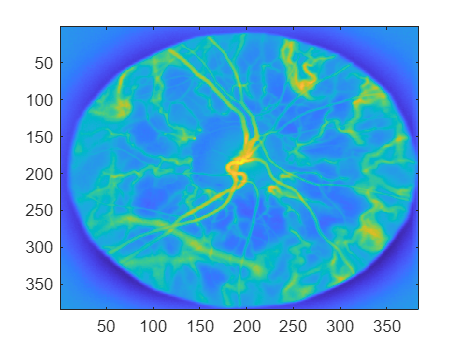

meanImg = mean(video,3);
imagesc(meanImg);

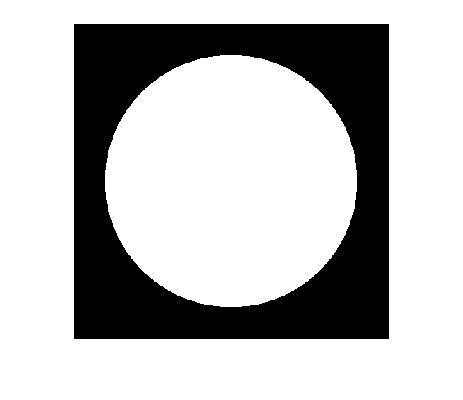

if true
    [x, y] = meshgrid(1:Ny, 1:Nx);
    diaphragm = sqrt((x - Nx/2) .^ 2 + (y - Ny/2) .^ 2) <= 0.4 * (Ny + Nx) / 2;
    imshow(diaphragm);
else 
    diaphragm = true([Ny,Nx]);
end

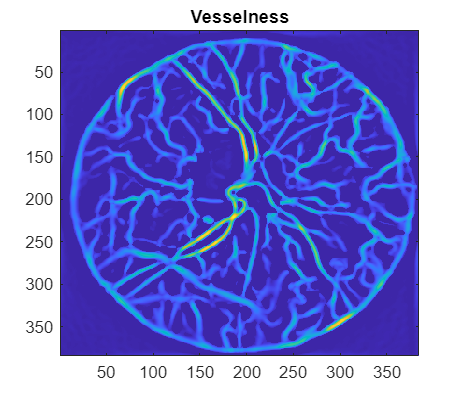

ContrastNumSlides = [100,100];
if false
    localContrastedImg = adapthisteq(rescale(meanImg), 'NumTiles', ContrastNumSlides);
else
    localContrastedImg = meanImg;
end
vesselness_sigma = 3;
vesselness_beta = 0.8;
vesselnessImg = vesselness_filter(localContrastedImg,vesselness_sigma , vesselness_beta);
imagesc(vesselnessImg)
title('Vesselness')

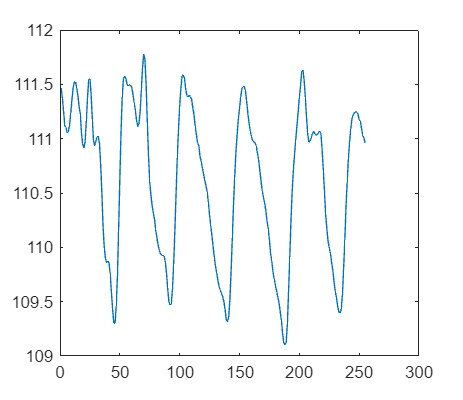

pulse = (sum(video.*diaphragm,[1,2])/nnz(diaphragm));
plot(squeeze(pulse));

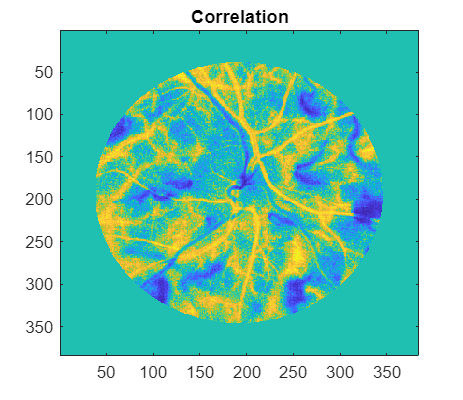

cor = mean((video-meanImg).*diaphragm .* (pulse-mean(pulse,3)),3)./(std((video-meanImg),[],3)*std(pulse-mean(pulse,3),[],3));
imagesc(cor);
title('Correlation')

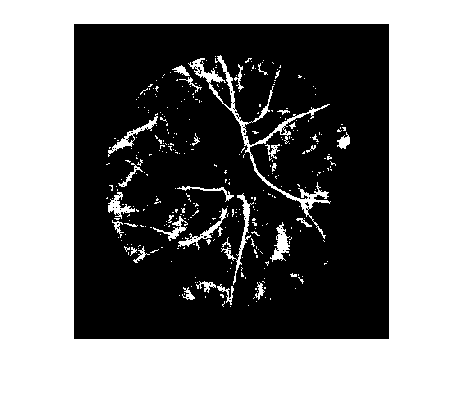

firstcorrelationThreshold = 0.52;
firstMaskArtery = cor>firstcorrelationThreshold;
imshow(firstMaskArtery)

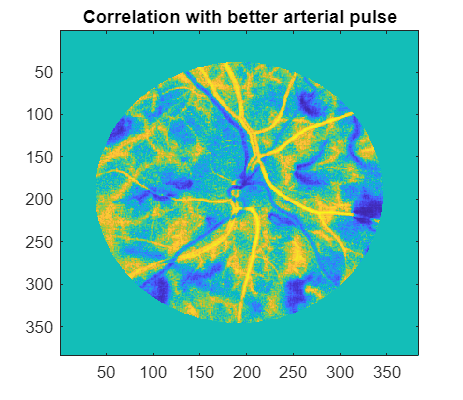

pulse_artery = (sum(video.*firstMaskArtery,[1,2])/nnz(firstMaskArtery));
cor_artery = mean((video-meanImg).*diaphragm .* (pulse_artery-mean(pulse,3)),3)./(std((video-meanImg),[],3)*std(pulse_artery-mean(pulse_artery,3),[],3));
imagesc(cor_artery);
title('Correlation with better arterial pulse')

cor_vein = - cor_artery;

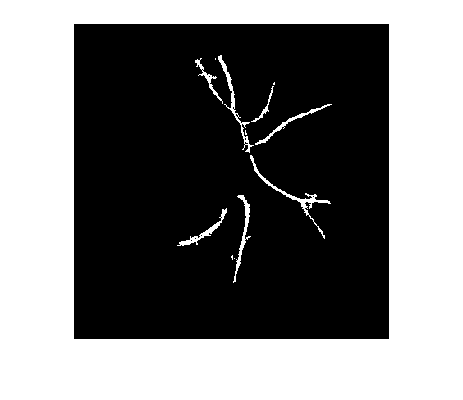

secondcorrelationThreshold = 0.66;
maskArtery = cor_artery>secondcorrelationThreshold;
num_parts=6;
maskArtery = bwareafilt(maskArtery,num_parts);
imshow(maskArtery)

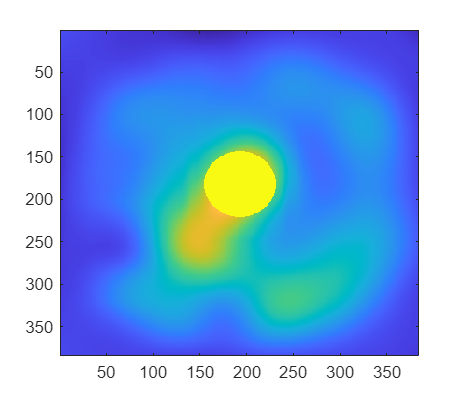


meanImM1 = squeeze(mean(videoCRA, 3));

blurred_mask = imgaussfilt(meanImM1, 26);

[y_barycentre, x_barycentre] = find(blurred_mask == max(blurred_mask, [], 'all'));

[x, y] = meshgrid(1:Ny, 1:Nx);
cercleMask = sqrt((x - x_barycentre) .^ 2 + (y - y_barycentre) .^ 2) <= 0.1 * (Ny + Nx) / 2;
blurred_mask(cercleMask) =max(blurred_mask,[],'all');
imagesc(blurred_mask)

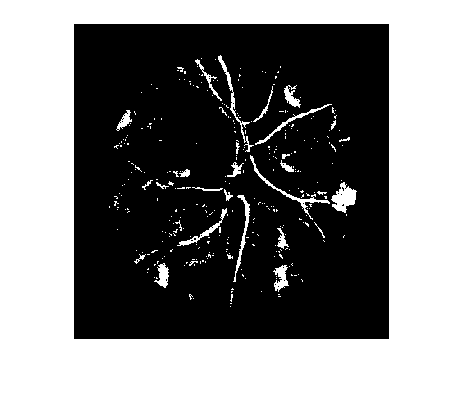


PW_params.RG_alpha = -0.005;
PW_params.RG_FloorThreshold = 0.61;

seeds = maskArtery;
condition = abs(cor_artery)>0.69;
imshow(condition);

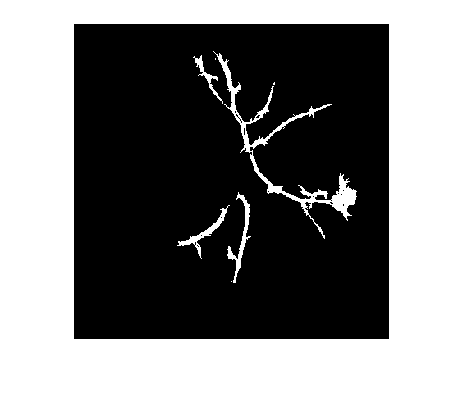

[maskArtery, ~] = region_growing_for_vessel(vesselnessImg, seeds, condition, path,PW_params);

imshow(maskArtery);

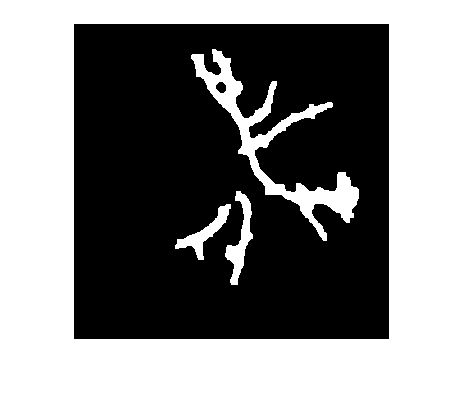

maskArtery = imdilate(maskArtery, strel('disk', 3));
maskArtery = imclose(maskArtery, strel('disk', 5));
imshow(maskArtery);